# Air density

clear;
close all;

[param, weather, route, driver] = loadData();

R = 8.1345; %J/mol/K
Mair = 28.96e-3; %kg/mol
p0 = 101325; %Pa
T = [10; 20; 30; 40] + 273.15; %K
g = getPhysicalConstants().g; %m/s^2

h = linspace(0, max(route.altiSmooth), 100);

Function

density = @(h,T) p0*Mair ./ (R*T) .* exp(-Mair*g*h ./ (R*T));

#### Plot

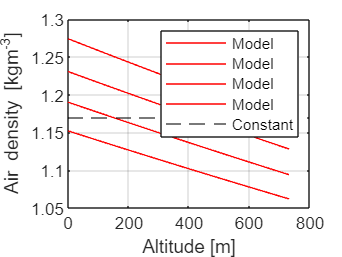

figure
plot(h, density(h,T), 'r', 'DisplayName', 'Model')
hold on
yline(param.aero.rhoAir, 'k--', 'DisplayName', 'Constant')
xlabel("Altitude [m]")
ylabel("Air density [kgm^{-3}]")
legend()
box on
grid on